# Detect Open and Close of Blinks

load data

i = 1;
XTrain = load(['DataSet\Test\Train\XTestTrain' num2str(i) '.mat']).XTestTrain;
YTrain = load(['DataSet\Test\Train\YTestTrain' num2str(i) '.mat']).YTestTrain;
XTest = load(['DataSet\Test\Test\XTestTest' num2str(i) '.mat']).XTestTest;
YTest = load(['DataSet\Test\Test\YTestTest' num2str(i) '.mat']).YTestTest;  

translate 'blink' to 'opening' and 'closing'

categroies = {'opening', 'closing', 'n/a', 'muscle-artifact'};
YTrain = generateOpeningClosing(XTrain, YTrain,categroies);
YTest = generateOpeningClosing(XTest,YTest,categroies);
locationTrain = YTrain{2};
locationTest = YTest{2};
YTrain = YTrain{1};
YTest = YTest{1};

TCN

optVars = load("HyperParameterSearch\OptVars\TCNoptVars.mat").optVars;
numFilters = optVars.numFilters;
filterSize = optVars.filterSize;
numBlocks = optVars.numBlocks;
dropoutFactor = optVars.dropoutFactor;
miniBatchSize = optVars.miniBatchSize;
learningrate = optVars.learningrate;
Maxepochs = 30;
rng(1);

layers = constructTCN(size(XTrain{1}, 1), numFilters, filterSize, numBlocks, dropoutFactor);

options = trainingOptions('adam', ...
    'MaxEpochs',Maxepochs, ...
    'MiniBatchSize',miniBatchSize, ...
    'InitialLearnRate',learningrate, ...
    'LearnRateDropPeriod',10, ...
    'LearnRateDropFactor',0.75, ...
    'LearnRateSchedule','piecewise', ...
    'Plots','training-progress',...
    'GradientThreshold',1, ...
    'shuffle','every-epoch',...
    'Verbose',0,...
    'DispatchInBackground',true);


net = trainNetwork(XTrain,YTrain,layers,options);
save(['Models\trainedModels\TCNOCnet.mat'],'net','-mat');

LSTM

optVars = load("HyperParameterSearch\OptVars\LSTMoptVars.mat").optVars;
miniBatchSize = optVars.miniBatchSize;
learningrate = optVars.learningrate;
numFeatures = 3;
numBlocks = optVars.numBlocks;
numHiddenUnits = optVars.numHiddenUnits;
numResponse = 4;
rng(1);

layers = constructLSTM(numFeatures,numBlocks,numHiddenUnits,numResponse,false); 

options = trainingOptions('adam', ...
    'MaxEpochs',30, ...
    'MiniBatchSize',miniBatchSize, ...
    'InitialLearnRate',learningrate, ...
    'LearnRateDropPeriod',10, ...
    'LearnRateDropFactor',0.75, ...
    'LearnRateSchedule','piecewise', ...
    'Plots','training-progress',...
    'GradientThreshold',1, ...
    'shuffle','every-epoch',...
    'Verbose',0,...
    'DispatchInBackground',true);
net = trainNetwork(XTrain,YTrain,layers,options);
save(['Models\trainedModels\LSTMOCnet.mat'],'net','-mat');


% evaluate
YPred = classify(net, XTest, "MiniBatchSize",miniBatchSize);
valError = 0;
for k = 1:length(YPred)
    valError = valError + mean(YPred{k} == YTest{k});
end
accuracy = valError/length(YPred);
TY = [];
Y = [];
YTest = YTest.';
for k = 1:numel(YTest)
    TY = [TY;YTest{k}];
    Y = [Y;YPred{k}];
end
confusionMat = confusionmat(TY(:),Y(:));
pred = YPred; 
locationPred = findBlinkFromOpeningClosing(Y,20);

TP = 0;
FN = 0;
FP = 0;
testNum = 0;
predNum = 0;
tolerance = 10;

for i = 1:numel(locationPred)
    testNum = testNum+numel(locationTest{i});
    predNum = predNum+numel(locationPred{i});
    if locationPred{i}

        for j=locationPred{i}
            
            if locationTest{i}
                
                for k=locationTest{i}
                    
                    if abs(j-k)<=tolerance
                        TP = TP+1;
                    end
                end
            else
                FP = FP + numel(j)-numel(locationTest{i});
            end
        end
    elseif numel(locationTest{i})-numel(locationPred{i}) > 0
        FN = FN + numel(locationTest{i})-numel(locationPred{i});
    end
end
TP,FN = testNum-TP,FP = predNum - TP,
figure;
confusionchart(confusionMat,categroies,RowSummary="absolute");
% LSTMresult = {confusionMat,locationPred,TP,FN,FP}
TCNresult = {confusionMat,locationPred,TP,FN,FP}

n=1;
for i = n:n+1
    figure;
    
    subplot(4,1,1);
    hold on;
    plot(TY(i,:));
    if locationTest{i}
        plot(locationTest{i}, categorical({'opening'}),'r^');
    end
    hold off;
    subplot(4,1,2);
    hold on;
    plot(Y(i,:));
    if locationTest{i}
        plot(locationPred{i}, categorical({'opening'}),'r^');
    end
    hold off;
    subplot(4,1,3);plot(XTest{i}');
    subplot(4,1,4);
end

polar    iq

Fp1Fp3 = load("DataSet\selected_and_segmented_eeg\fp1_fp3_iq.mat").fp1_fp3_iq;
Fp4Fp4 = load("DataSet\selected_and_segmented_eeg\fp2_fp4_iq.mat").fp2_fp4_iq;
Ds = {};
rawDs={};
windowLength = 4;
fs = 250;

for i = 1:size(Fp1Fp3,1)
    filteredSignals = passbandBlinks(table(Fp1Fp3(i,:)',Fp4Fp4(i,:)',Fp1Fp3(i,:)'/2),fs);
    rawDs{end+1} = filteredSignals;
    filteredSignals = array2table(resample(filteredSignals.Variables, slice, windowLength*fs),  'VariableNames', filteredSignals.Properties.VariableNames);
    Ds{end+1} = filteredSignals;
end

load other data EEG IQ Test Experiment (Rafal Paprocki and Artem Lenskiy Dataset)

currentDir = dir("DataSet\ModelApplication\EEG IQ Test Experiment");
currentDir(1:2) = [];
fs = 250;
dsFactor = 2048;
slice = 512;
windowLength = 4; %4
Ds = {};
rawDs = {};
frontElectrodesLabels = ["Fp1", "Fp2", "Fz"];
for i = 1:numel(currentDir)
    eegTable =  readtable([currentDir(i).folder '\' currentDir(i).name]);
    subj = eegTable(:, ["Var1","Var2","Var5"]);

    filteredSignals = passbandBlinks(subj, fs);
    rawDs{end+1} = filteredSignals;
    filteredSignals = array2table(resample(filteredSignals.Variables, slice, windowLength*fs),  'VariableNames', filteredSignals.Properties.VariableNames);
   
    Ds{end+1} = filteredSignals;
end

blinkLocations = {};
predLocations = {};
predLables = {};
chopedDs = {};
shiftChopedDs={};
slice = 512;

for i = 1:numel(Ds)
    tic;
    oneSubj = {};
    shiftSubj = {};
    for j = 1:slice:size(Ds{i},1)-slice
        oneSubj{end+1,1} = table2array(Ds{i}(j:j+slice-1,:))';        
    end
    chopedDs{i} = oneSubj;
    shiftChopedDs{i} = shiftSubj;

    
    X = oneSubj;
    sX = shiftSubj;

    YPred = classify(net,X);
    
    lable = [];sLable = [];
    blinkLocation = [];
    
    for k = 1:size(YPred)

        lable = [lable,YPred{k}];
    end  
    blinkLocation = findBlinkFromOpeningClosing(lable);

    
    predLocations{i} = blinkLocation;
    predLables{i} = lable;
    toc,length = size(Ds{i},1)
end

manual fix

clear cursor_info;
location = predLocations{i}{1};
% subName = numlist{i};
coordinate = rawDs{i}.Var1(floor(predLocations{i}{1}));
missed = [];

fig=figure(1);
a=datacursormode(fig);
hold on;
plot(rawDs{i}.Var1);
plot(location,coordinate,'r*');
hold off;
% pause();% save cursor_info to work space

location = sort([location,floor(struct2table(cursor_info).Position(:,1))']);

Applying

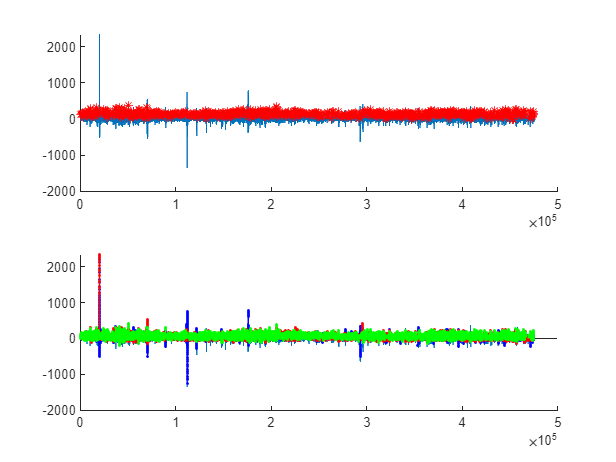

        clear cursor_info; 
for i=25
    % right click on data tip -> save to work space
    fig=figure(1);
    a=datacursormode(fig);
    signal = table2array(rawDs{i});
    signal = signal(:,1);
    location = round(predLocations{i}{1}*windowLength*fs/slice);

    lables = predLables{i};
    figure;
    coordinate = signal(location);
    subplot(2,1,1);
    hold on;

    plot(signal);
    plot(location,coordinate,'r*');
    hold off;


    subplot(2,1,2);
    hold on;
    plot(signal);
    stem(round(find(lables == "muscle-artifact")*fs*windowLength/slice),signal(round(find(lables == "muscle-artifact")*fs*windowLength/slice)),LineWidth=1,Color='b',MarkerSize=1);
%     stem(round(find(lables == "n/a")*fs*windowLength/slice),signal(round(find(lables == "n/a")*fs*windowLength/slice)),LineWidth=1,Color='b',MarkerSize=1);
    stem(round(find(lables == "opening")*fs*windowLength/slice),signal(round(find(lables == "opening")*fs*windowLength/slice)),LineWidth=1,Color='r',MarkerSize=1);
    stem(round(find(lables == "closing")*fs*windowLength/slice),signal(round(find(lables == "closing")*fs*windowLength/slice)),LineWidth=1,Color='g',MarkerSize=1);
    
    hold off;

end

blinkLocations = load("DataSet\ModelApplication\blinkLocations.mat").blinkLocations;
missedLocation = floor(struct2table(cursor_info).Position(:,1))';
    location = sort([location,missedLocation]);
    blinkLocations{end+1} = {location,currentDir(i).name,missedLocation};
    save("DataSet\ModelApplication\blinkLocations.mat","blinkLocations",'-mat');